Prueba cubo HSV (scatter plot de los valores HSV de la imagen)

ROPtest es la imagen cruda completa y ROPgold es la imagen de sólo fondo ocular, segmentada a mano la lupa.

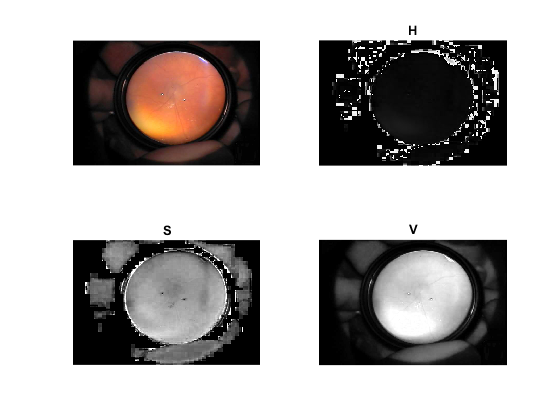

cd 'E:\- Documents\BIO\Administrativo\Proyecto Final Hernan Rodriguez\';
a=imread('ROPtest11.png');
a=im2double(a);
HSV=rgb2hsv(a);
figure;
subplot 221; imshow (a);
subplot 222; imshow (HSV(:,:,1));title H;
subplot 223; imshow (HSV(:,:,2));title S;
subplot 224; imshow (HSV(:,:,3));title V;

reformateo la matriz de 3 dimensiones H,S,V a una matriz de la totalidad de los pixeles con sus valores H,S,V (las columnas son H,S,V y los renglones, cada pixel)

rtest=reshape(HSV,numel(a(:,:,1)),3);

muestro el scatter plot de los valores HSV de los pixeles de la imagen cruda

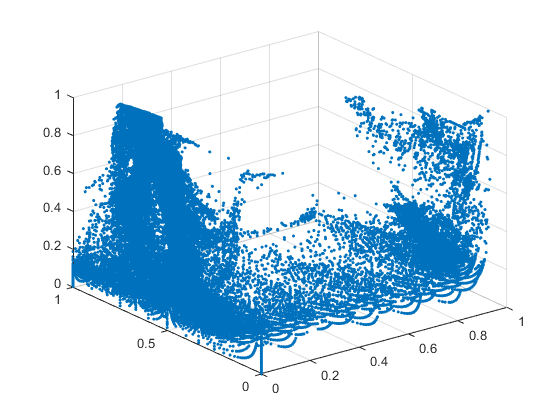

figure;
scatter3(rtest(:,1),rtest(:,2),rtest(:,3),'.');

Repito con la imagen ROPgold:

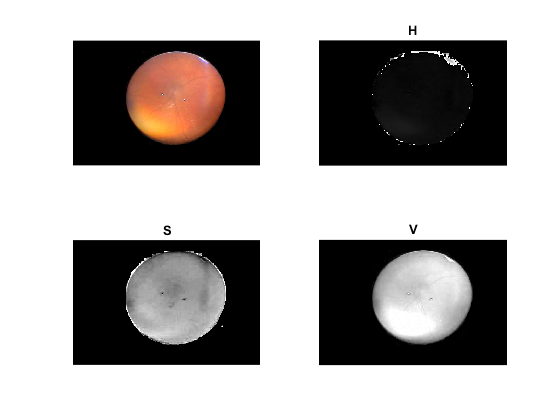


b=imread('ROPgold11.png');
b=im2double(b);
HbSbVb=rgb2hsv(b);
figure;
subplot 221; imshow (b);
subplot 222; imshow (HbSbVb(:,:,1));title H;
subplot 223; imshow (HbSbVb(:,:,2));title S;
subplot 224; imshow (HbSbVb(:,:,3));title V;

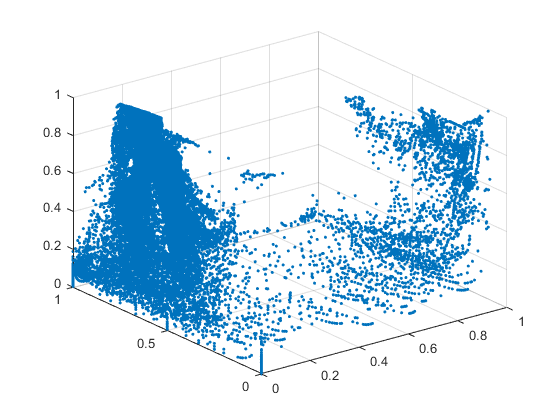

rgold=reshape(HbSbVb,numel(b(:,:,1)),3);
figure;
scatter3(rgold(:,1),rgold(:,2),rgold(:,3),'.');

A ojo, del paper de Estrada: 0<H<0.15; 0.45<V<1; 0.5<S<0.9 (junto con resultado del scatter plot del ROPgold) VARIABLES, ABAJO:

H=HSV(:,:,1);S=HSV(:,:,2);V=HSV(:,:,3);
Hmin=0; Hmax=0.2;
Smin=0.4; Smax=1;
Vmin=0.45; Vmax=1;
mask=zeros(size(a,1,2));
salida=zeros(size(a));

for i=1:size(a,1)
    for j=1:size(a,2)
    if (((H(i,j) >= Hmin) && (H(i,j) <= Hmax))...
            && ((S(i,j) >= Smin) && (S(i,j) <= Smax))...
            && ((V(i,j) >= Vmin) && (V(i,j) <= Vmax)))
        mask(i,j)=1;
        salida(i,j,1)=H(i,j);
        salida(i,j,2)=S(i,j);
        salida(i,j,3)=V(i,j);
    elseif mask(i,j)
    end
    end
end


Horrible la implementación del recorte de subespacio HSV, debe optimizarse

Se puede limpiar la máscara con morfologia binaria... HACERLO

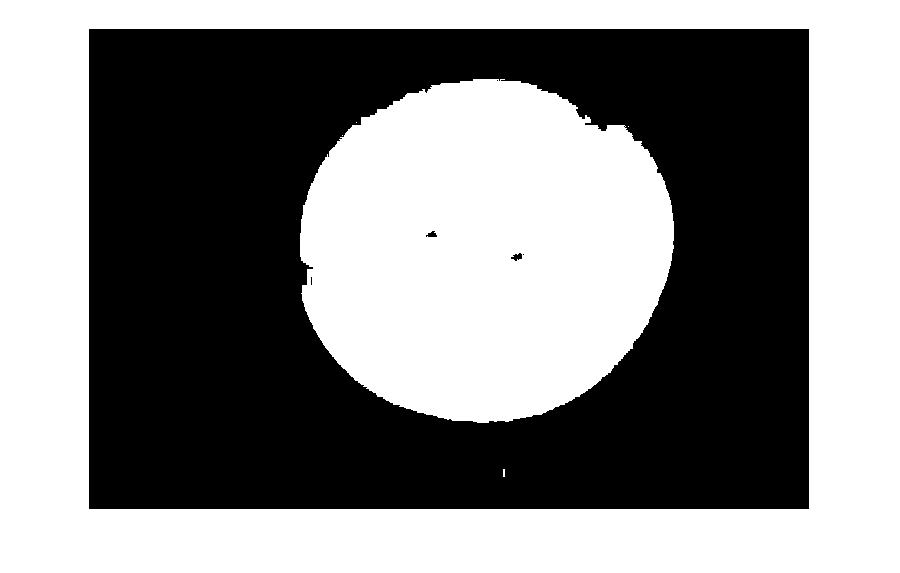

figure; imshow(mask);

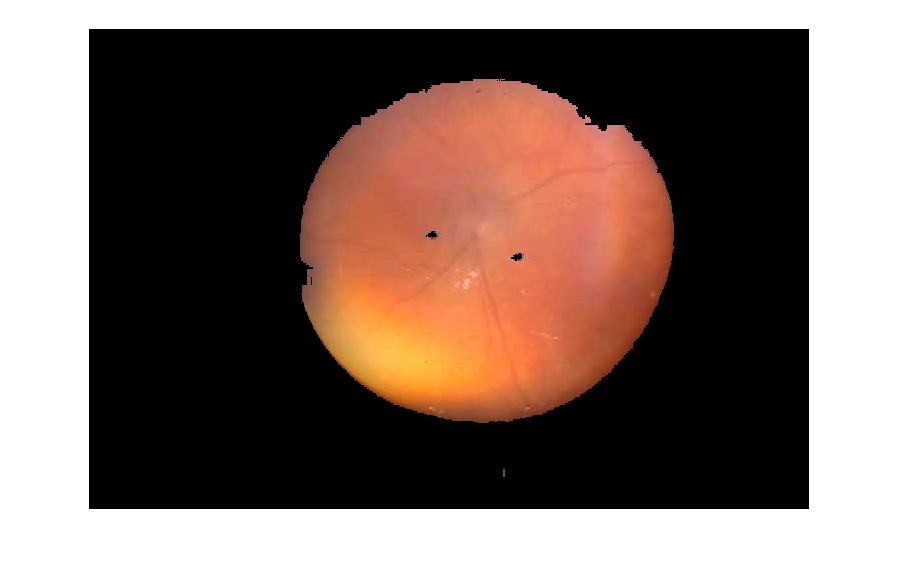

salida=hsv2rgb(salida);
figure; imshow(salida);